clear all;
close all;


**DEFINIZIONE DEL SISTEMA**

p=20; %in relta il valore può variare tra 20 e 35
G1 = zpk([],[-p,-220],2200)


G1 =
 
       2200
  --------------
  (s+20) (s+220)
 
Continuous-time zero/pole/gain model.



G2 = zpk([],[0,-7],7)


G2 =
 
     7
  -------
  s (s+7)
 
Continuous-time zero/pole/gain model.



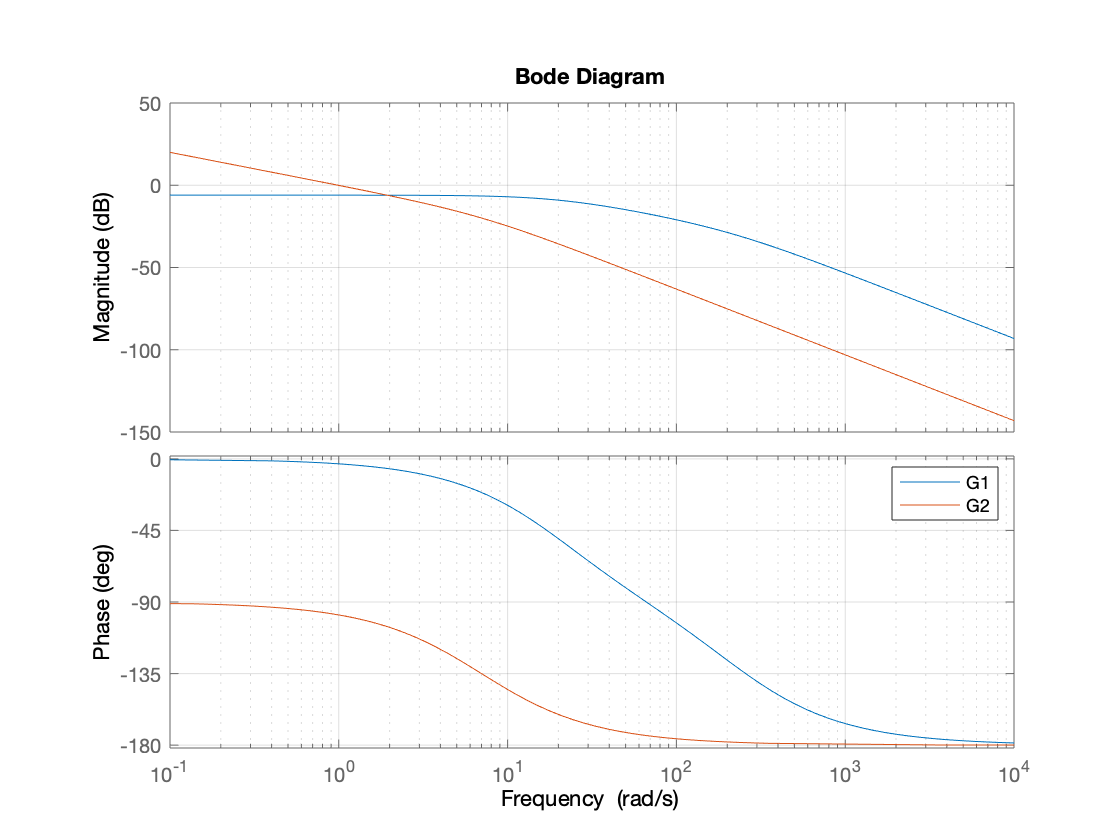

bode (G1);
[num_G1,den_G1] = tfdata(G1,'v');
hold on;
bode (G2); grid on; legend ();
hold off;

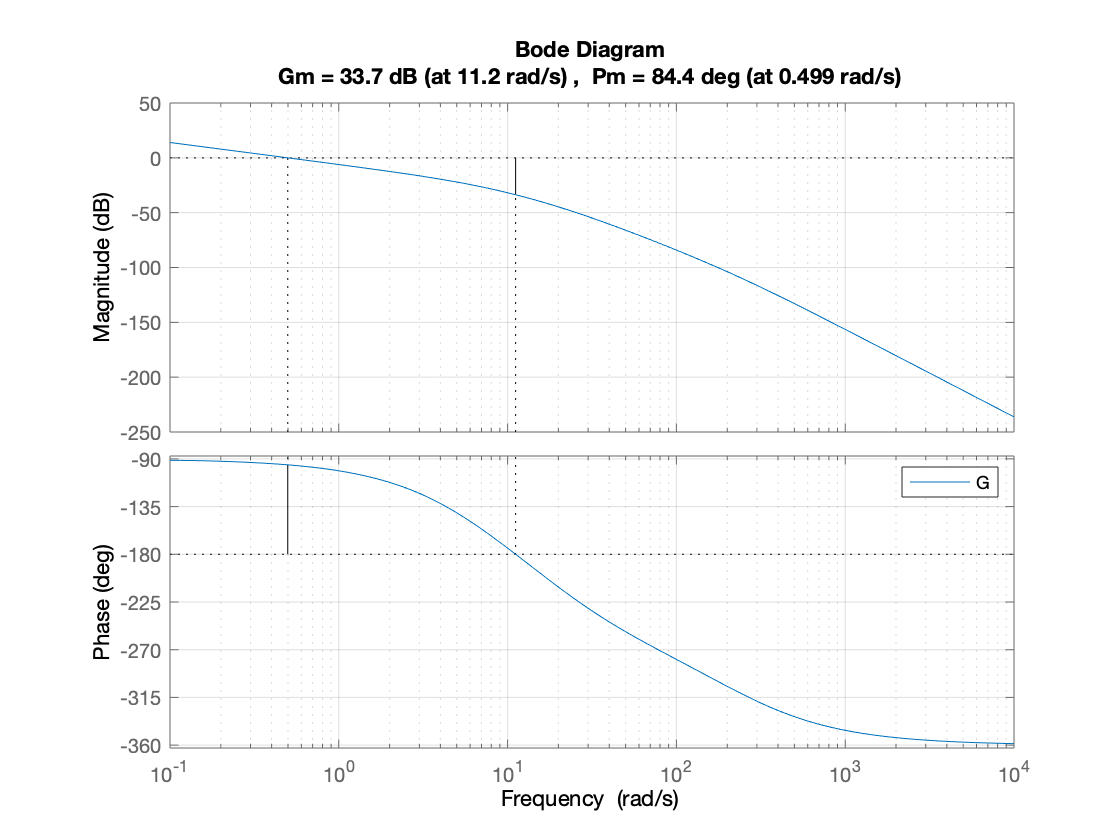

[num_G2,den_G2] = tfdata(G2,'v');
G = G1*G2;
margin (G); grid on; legend ();

**CONTROLLO IL SISTEMA SENZA SFRUTTTARE IL CONTROLLO IN CASCATA**

Per attenuare il disturbo d1 che esiste nell'intervallo [0;1] r/s uso un guadagno statico, calcolato grazie al *teorema del regime permante *da cui si deduce che ad 1 r/s la L(s) deve avere un modulo maggiore di 38.06 dB (quindi considerando che la G1(s) inizialmente è -11 dB il mu deve portare un'amplificazione di 49.06 dB). Dato il polo incerto in G2, quello con specifiche peggiori in questo caso è p = 35.

Per avere l'inseguimento di W e quindi errore nullo mi basta il polo nell'origine già presente in G2, come verificabile tramite il *teorema del valore finale.*

PROGETTO DEL REGOLATORE STATICO

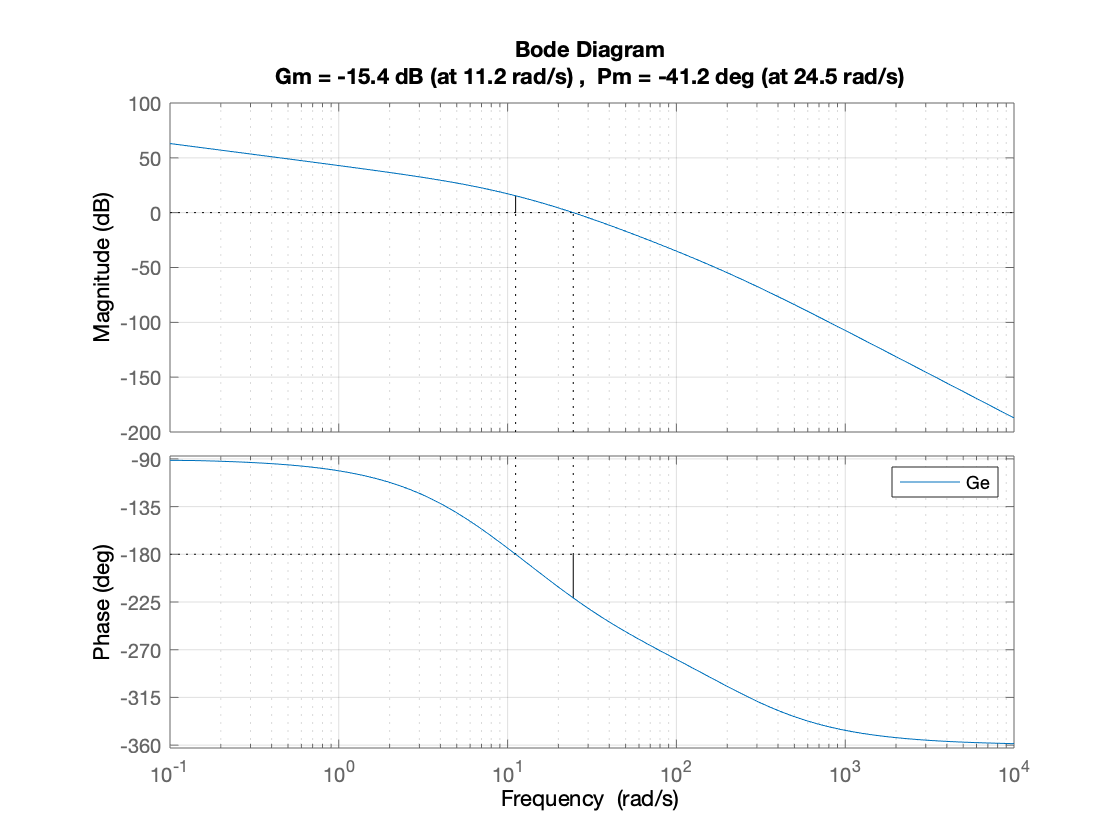

mu = 283.79; % mu_dB = 49.06
Ge = G*mu;
margin (Ge); grid on; legend ();

PROGETTO DEL REGOLATORE DINAMICO

Le specifiche sulla sovraelogazione, che deve essere nulla, impongono un  𝛿 ≥ 0.75. Attraverso le formule approssimate posso anche dedurre un Mf = 75º che è però maggiore di quello richiesto dalle specifiche del progetto. Decido dunque di seguire la specifica Mf=40º, perchè richiedere troppo margine di fase implica l'utilizzo di più zeri per guadagnare fase, rischiando di avere grossi problemi di code di assestamento. Ovviamente un margine di fase minore mi comporta una sovraelongazione fuori specifica che verrà attenuta con un pre-filtro passa basso.

Data la specifica sul tempo di assestamento (Ta_5% = 0.4 sec) è possibile ricavare il lower-bound (ω_c ≥ 10 r/s)  per la pulsazione di attraversamento della L(s), sapendo che ω_n = ω_c e che 𝛿 = 0.75.

Invece per attenuare il disturbo di misura n2, che agisce ad una frequenza di 8000 r/s con ampiezza 0.02,  ricaviamo l'upper-bound ω_c ≤ 800 r/s (una decade prima di n2).

Dato che dobbiamo recuperare più di 80º di fase sicuramente non basterà una sola rete anticipatrice. Decido quindi di usare due reti anticipatrici calibrate con il metodo del tuning pratico. Ho provato diverse pulsazioni di attraversamento decidendo alla fine di attraversare a 45 r/s, perchè è un buon compremesso per avere una fase non troppo degradata con un controllo non troppo nervoso, e allo stesso tempo una pulsazione di attraversamento maggiore di quella di Ge(s) (perchè il modulo deve essere negativo per le reti anticipatrici). 

Le due reti sono progettate in modo da guadagnare ognuna metà della fase richiesta e amplificare per metà del modulo che manca.

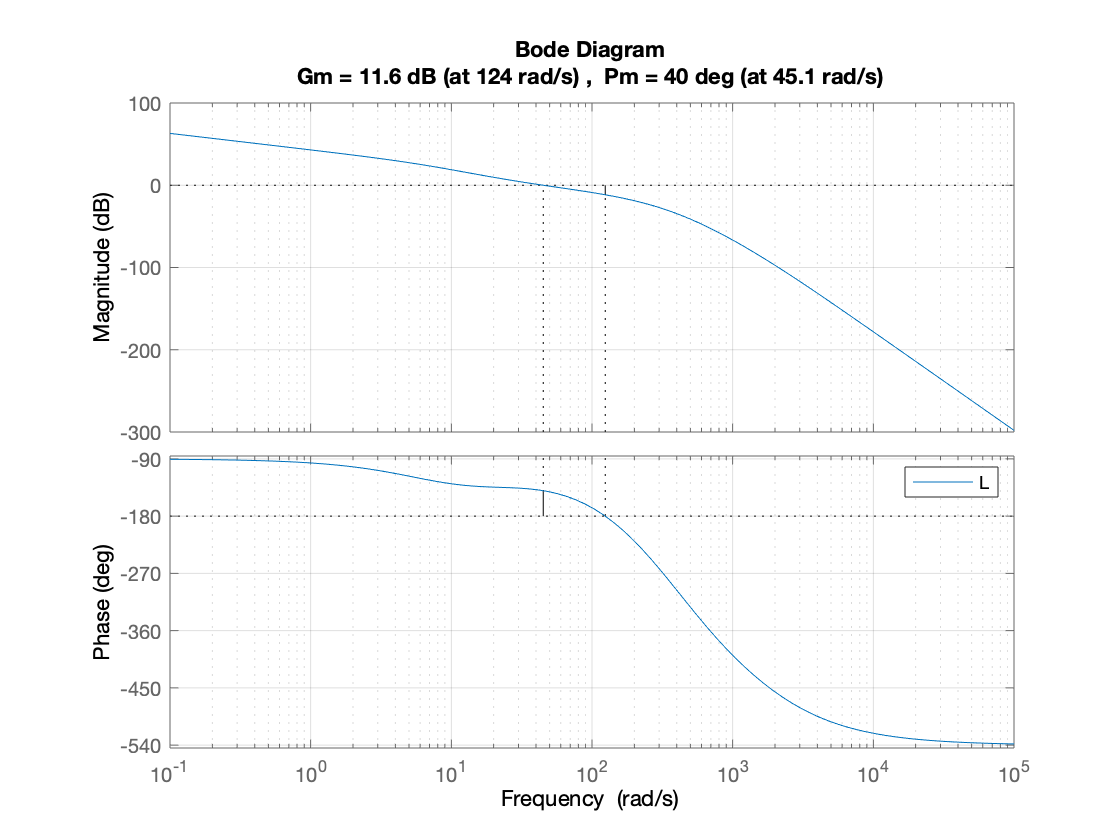

s=tf('s'); %definisco la variabile laplaciana
%Tuning pratico delle reti
alpha = 0.05;
tau = 0.046;
Rd1 = ((tau*s + 1)/(alpha*tau*s + 1))^2; % 2 reti anticipatrici progettate

Rd2 = 1/(((s/400)+1)*((s/1800)+1)); % poli di fisica realizzabilità per attenuare la Q
%e avere grado relativo del regolatore pari 2 
Rd = Rd1*Rd2;
[num_Rd,den_Rd] = tfdata(Rd,'v');

L = Rd*Ge;
margin (L); grid on; legend ();

Per il polo varibile p, il valore più critico per quanto riguarda la fase è p=20.

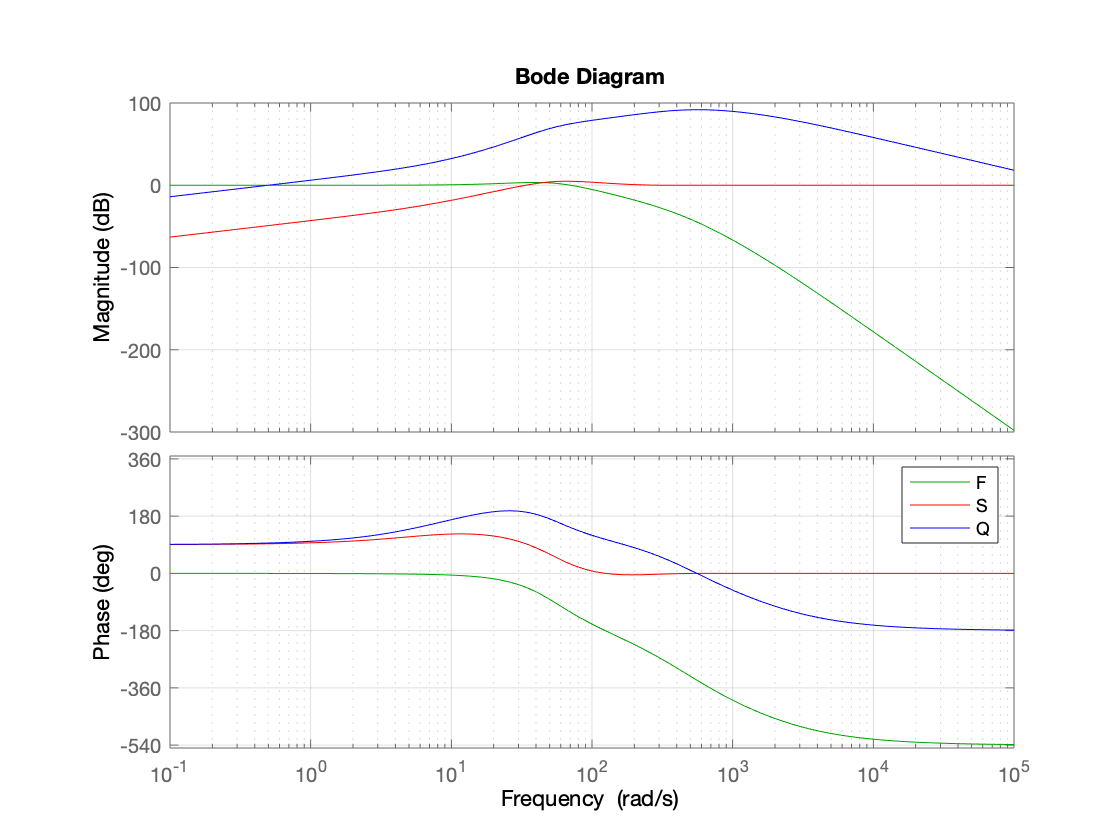


%Definisco tutte le funzione di sensitività del sistema
F = L/(L+1);
S = 1/(L+1);
Q = (Rd*mu)/(L+1);
%Plot di tutte le funzione di sensitività nello stesso bode
bode (F, 'green');
hold on;
bode (S, 'red');
hold on;
bode (Q, 'blue');
hold on; grid on; legend ();
hold off;

SISTEMA INIZIALE

Valuto quali sono i valori temporali del sistema inziale, prima che venga aggiunto il regolatore per poterli poi confrontare con il sistema controllato. In particolare mi interessa la variabile di controllo 'u' e i suoi valori.

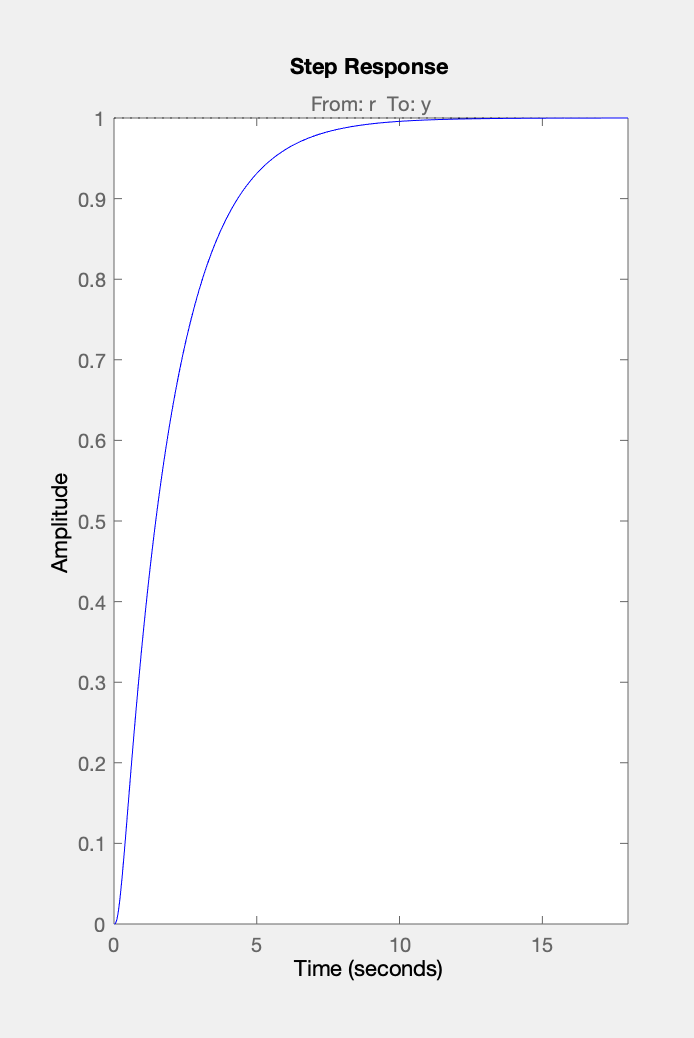

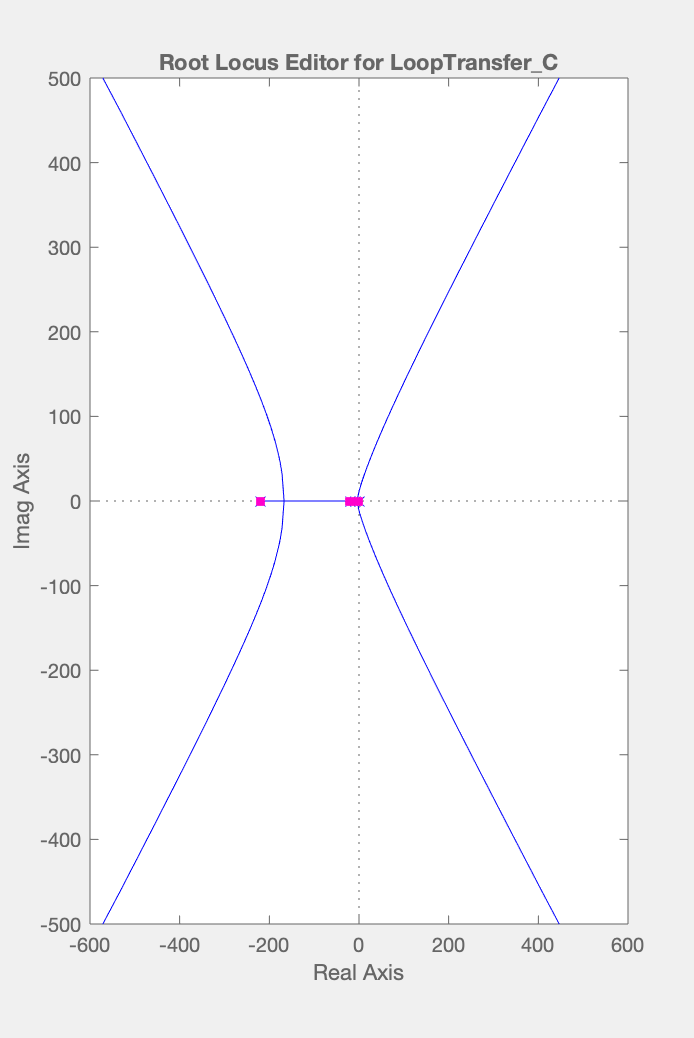

% dcgain (s*G);
rltool (G); %Per stabilizzare uso il root locus. La risposta temporale che si ottiene con

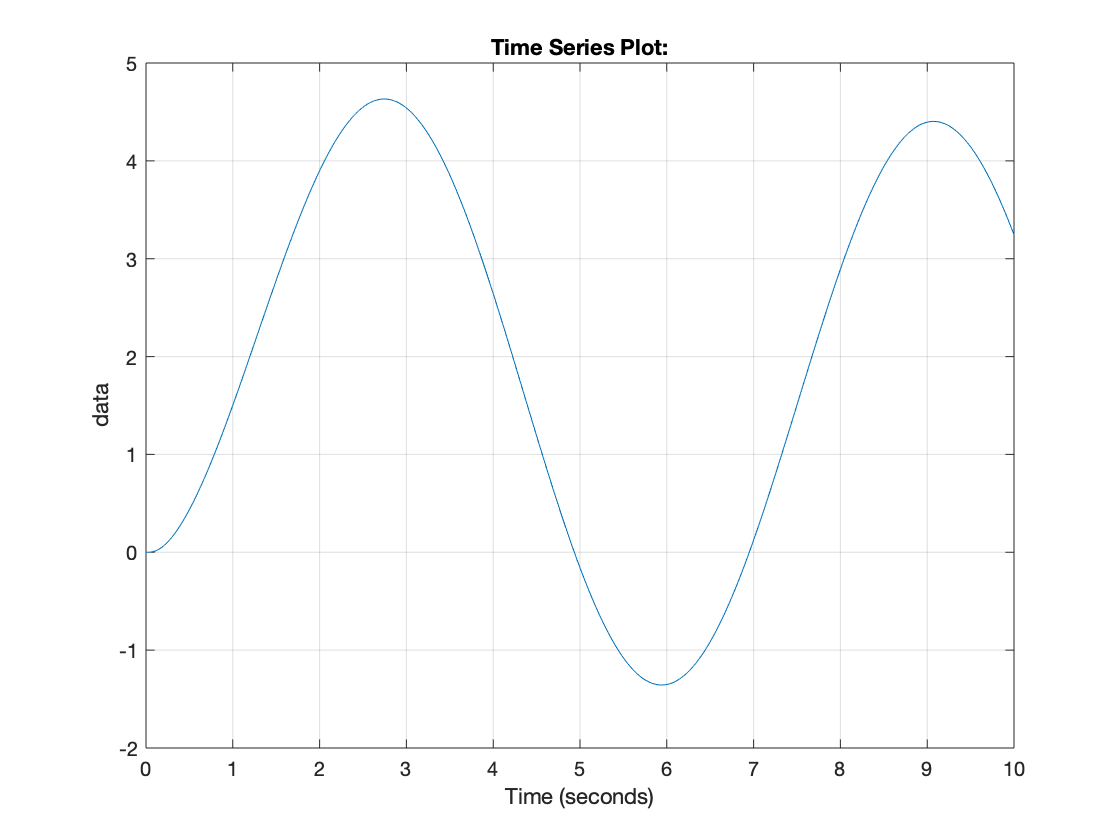

% rltool non tiene conto dei disturbi sul sistema, ma utile per capire la
% stabilità di G(s)
run sistema_iniziale.slx;
sim('sistema_iniziale');
plot(out.yi); grid on;

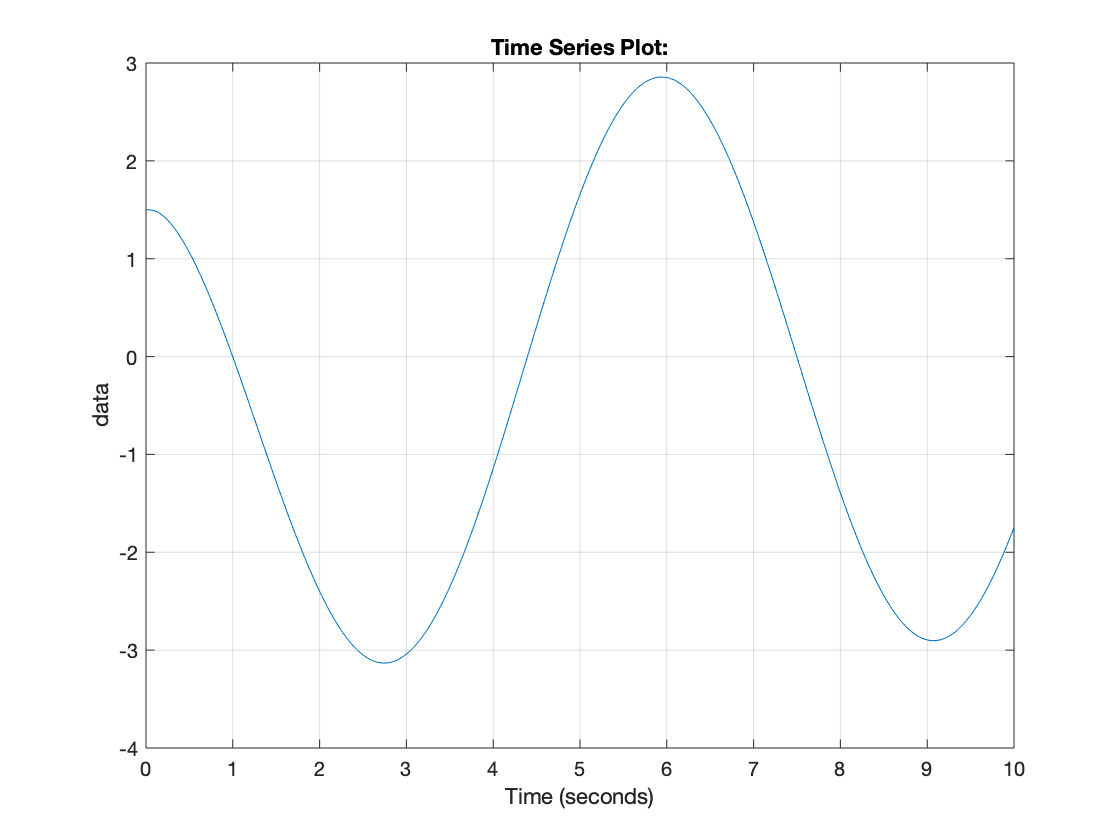

plot(out.ui); grid on;

SIMULAZIONE TEMPORALE DEL SISTEMA CONTROLLATO

Richiamo lo schema di Simulink per guardare quale è la risposta al gradino del sistema con Regolatore. 

Per evitare problemi con la simulazione dello schema simulink che comprende già anche il prefiltro e il filtro anti-aliasing, faccio in modo che questi non disturbino i miei risultati.

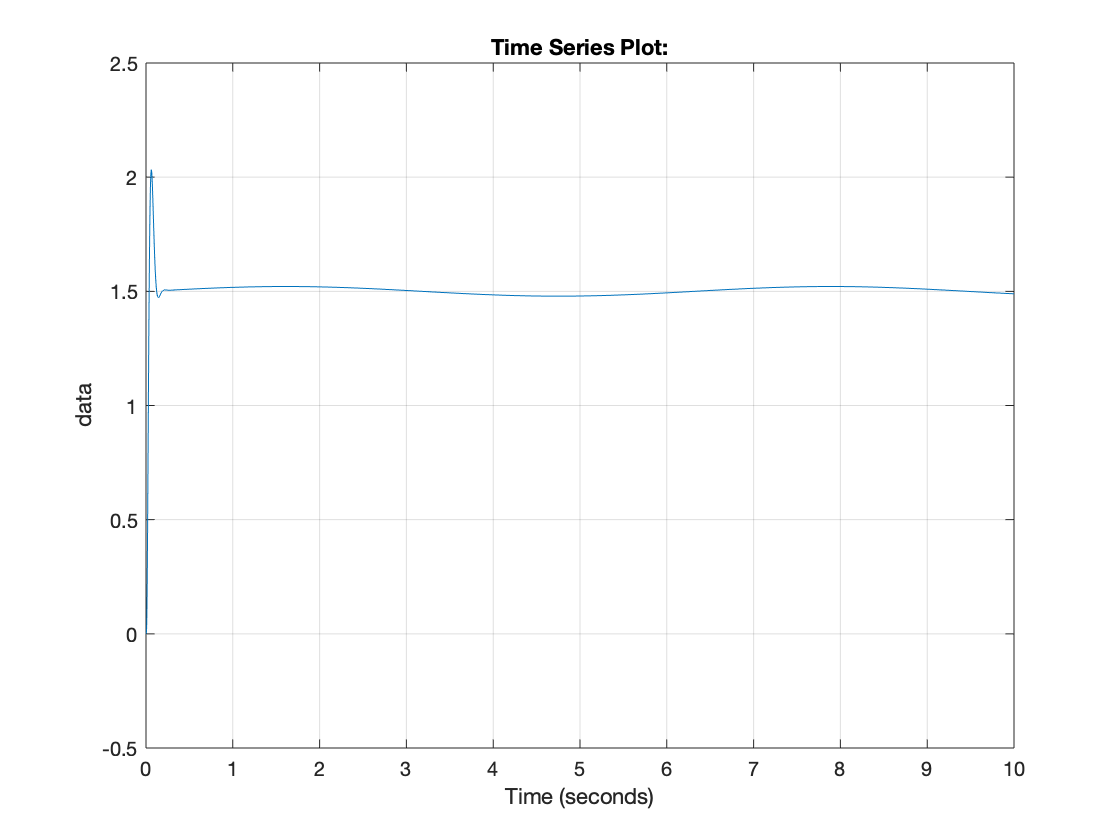

num_Rpf = 1;
den_Rpf = 1;
num_Raa = 1;
den_Raa = 1;
%componenti discreti
NUMd = 1;
DENd = 1;
NUMpf = 1;
DENpf = 1;
%metto un tempo di campionamento qualunque per evitare errori simulink
Ts = 1;

run sistema_controllato.slx;
sim('sistema_controllato');
plot(out.y); grid on;

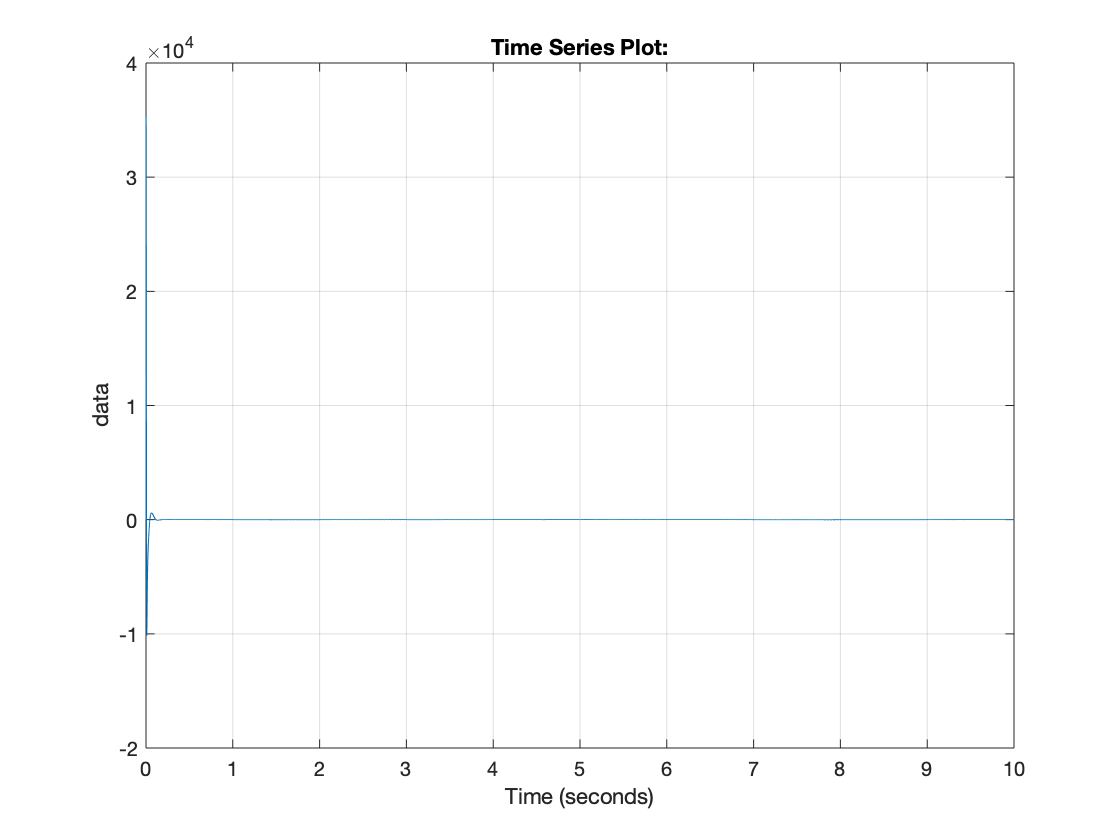

plot(out.u); grid on;

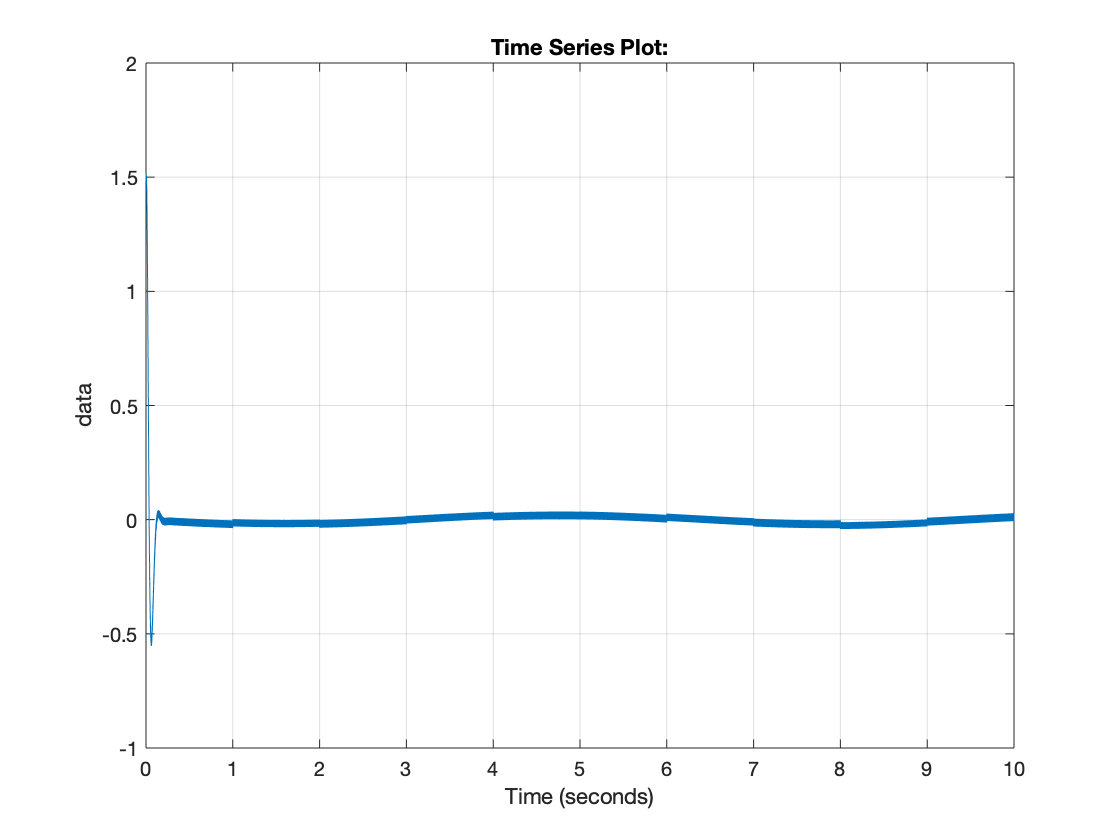

plot(out.e); grid on;

Si nota subito un overshoot eccessivo e un tempo di assestamento che invece rispetta ampiamente le specifiche permettendomi di utilizzare un pre-filtro passa basso per attenure la sovraelongazione. Altro benificio derivante dall'utilizzo del pre-filtro è la moderazione della variabile di controllo. 

Per il polo varibile p, il valore più critico per quanto la sovraelongazione è p=20.

INTRODUZIONE DEL PRE-FILTRO

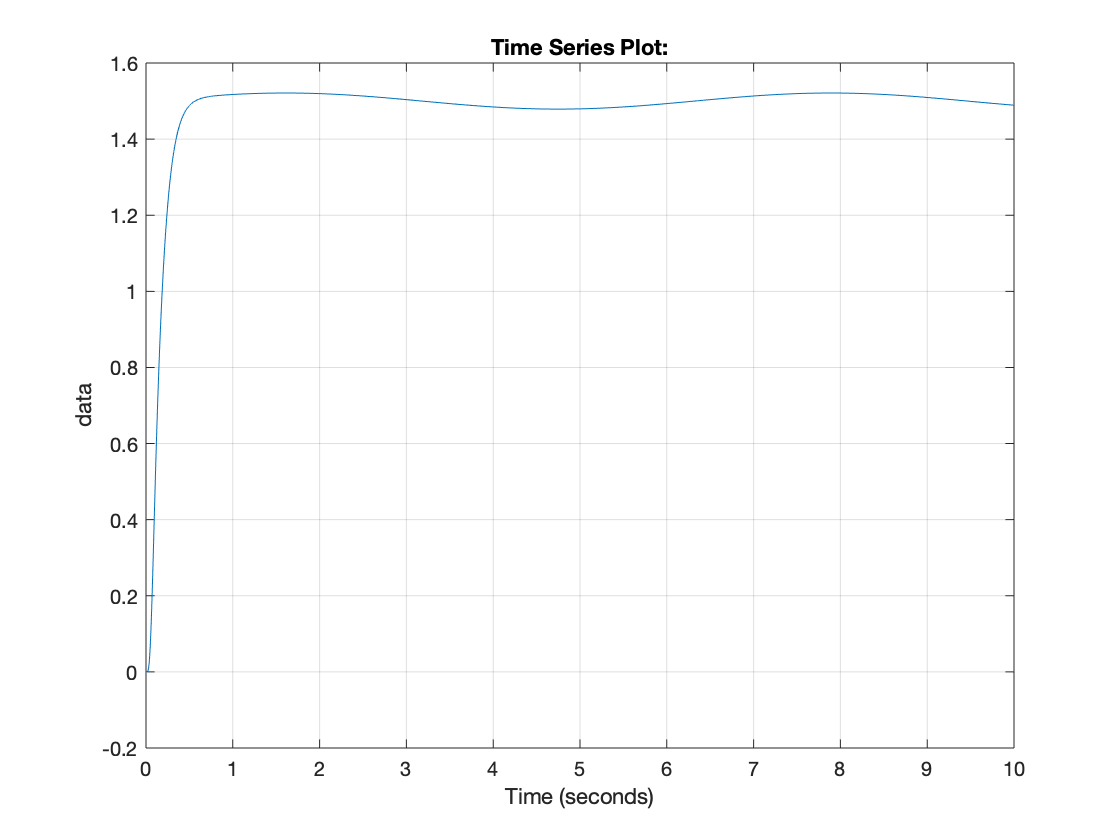

%Scelgo una pulsazione di taglio per il mio filtro omega_c=8 e quindi tauf=0.65/omega_c 
%per filtro di 2º ordine
tauf = 0.081; % tau-filtro. 

Rpf= 1/(1+tauf*s)^2; %filtro del secondo ordine con omega_c=8
[num_Rpf,den_Rpf] = tfdata(Rpf,'v');


run sistema_controllato;

sim('sistema_controllato');
plot(out.y); grid on;

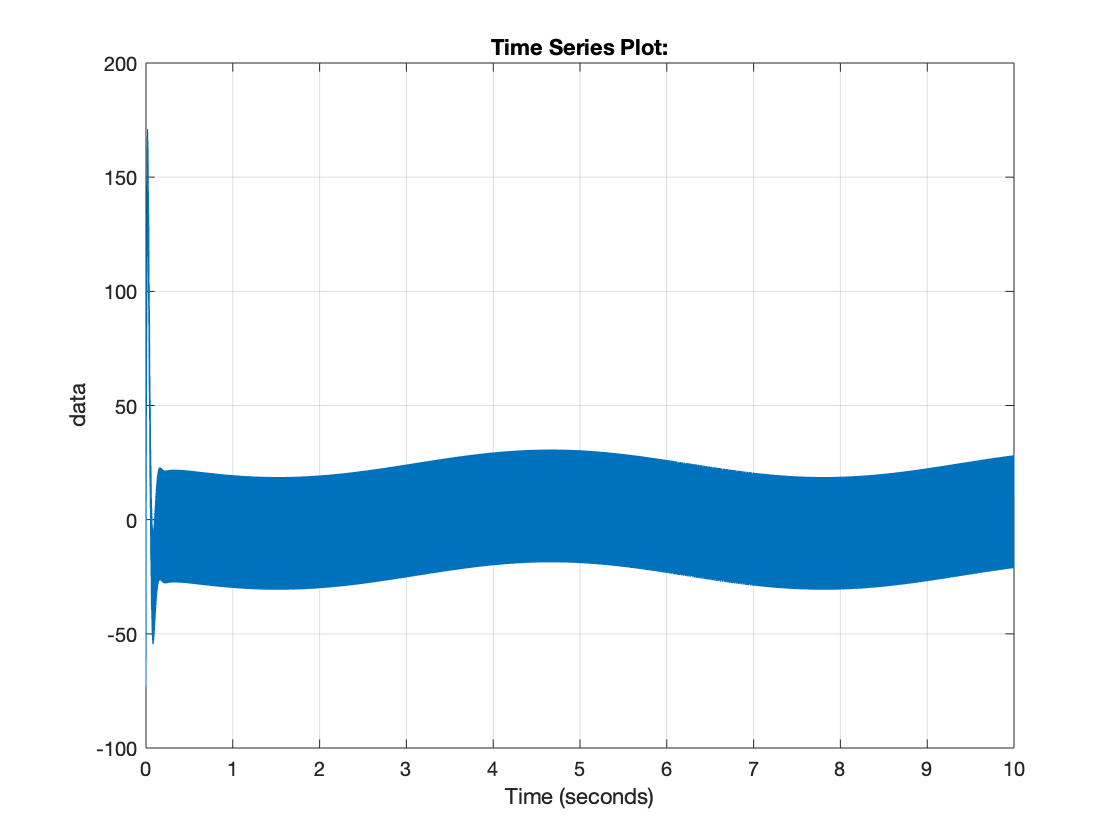

plot(out.u); grid on;

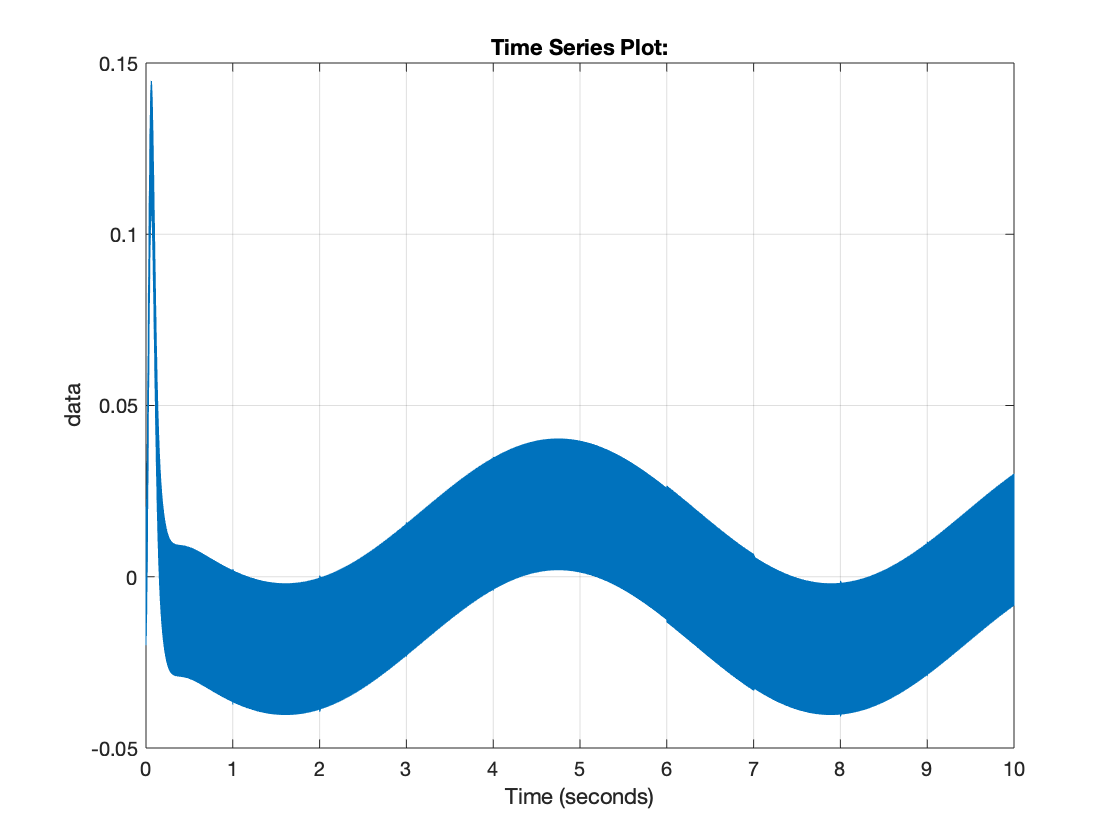

plot(out.e); grid on;

Grazie al pre-filtro ottengo un sistema privo di overshoot e con una variabile di controllo decisamente più moderata. 

DISCRETIZZAZIONE DEL REGOLATORE

Poiché il regolatore è stato progettato come tempo continuo è necessaria un'interfaccia D/A per la discretizzazione del regolatore. Per fare questo ho utilizzato il teorema di Shannon e la "regola pratica" ad esso associata, che mi hanno permesso di determinare un intervallo di valori validi per il tempo di campionamento, andando poi a scegliere quello più adeguato al mio progetto. L'alpha scelto per applicare la "regola pratica" è la media tra 5 e 10 (cioè 7.5).

Per evitare poi il fenomeno dell'aliasing ho introdotto un filtro anti-aliasing con:                                         omega_c < omega_aa < omega_s/2

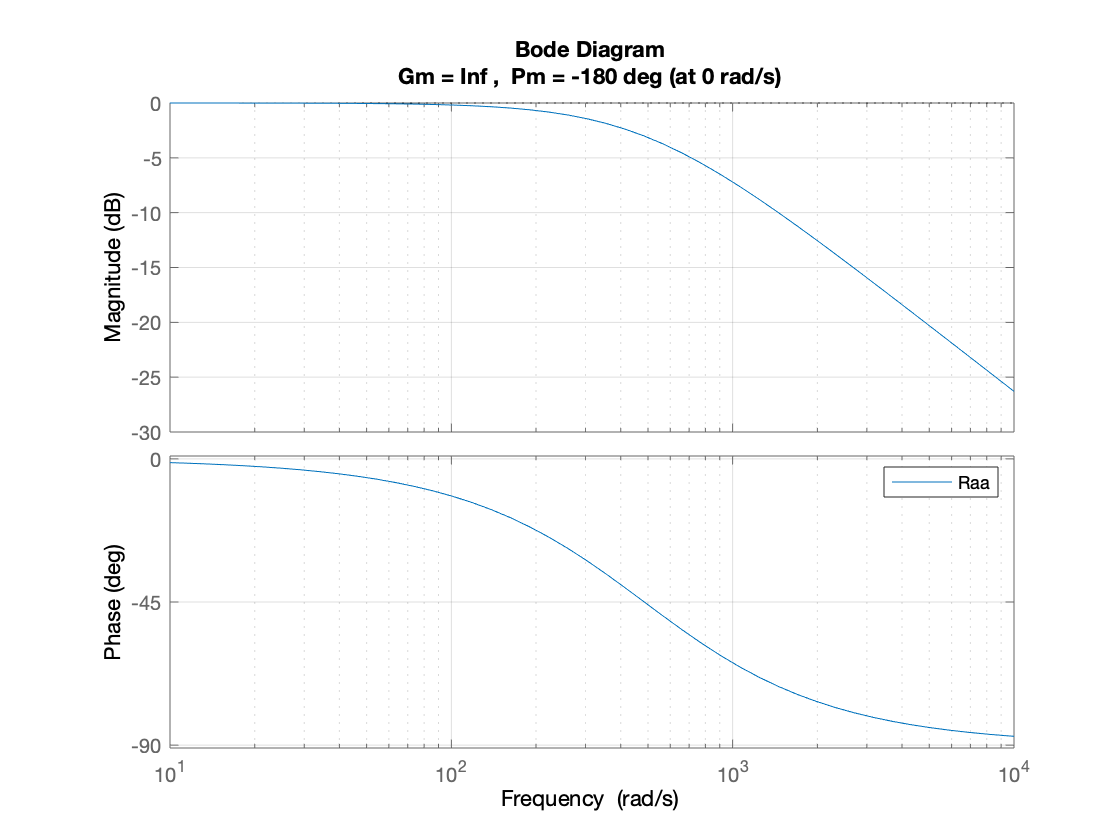

%Il valore della omega_c è 45r/s quindi 337.5 < omega_s < 3375 da cui  
% 1.86*10^(-3) < omega_s < 0.019
omega_s = 3000; %1850 valore che causa un peggioramento della u, se metto 
%invece 3300 la u migliora ancora di più
Ts = 2*pi/omega_s;

% filtro anti-aliasing con w_aa=485r/s. Abbassando la w_aa si può
% modificare sostaziosamente la u. 485 è il valor medio che si ha se
% omega_s = 1850
tau_aa=1/485;
Raa=1/((s*tau_aa)+1);
margin (Raa); grid on; legend ();

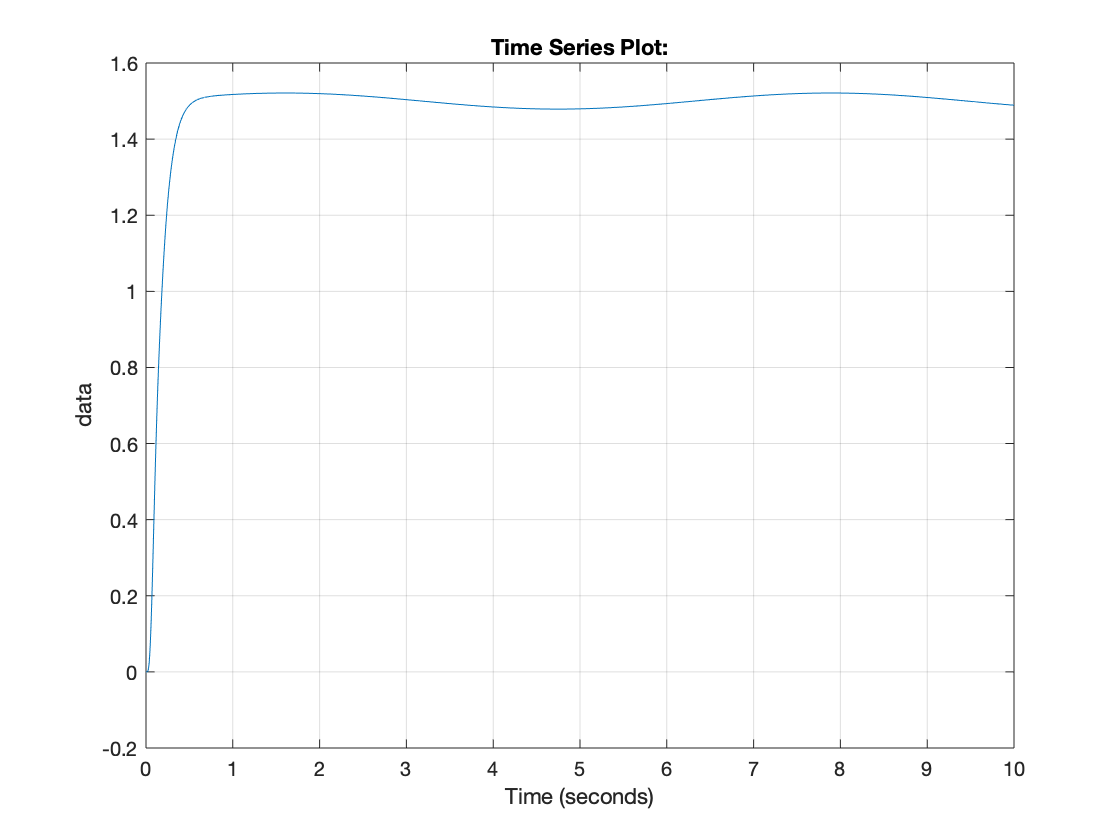

[num_Raa,den_Raa] = tfdata(Raa,'v');


R = Rd*mu;
[num_R,den_R] = tfdata(R,'v');
%funzioni per discretizzare le f.d.t in ingresso
[NUMd,DENd] = c2dm (num_R,den_R,Ts,'tustin');
[NUMpf,DENpf] = c2dm (num_Rpf,den_Rpf,Ts,'tustin');


%(sostituire i componenti continui con quelli discreti)
sim('sistema_controllato');
plot(out.y); grid on;

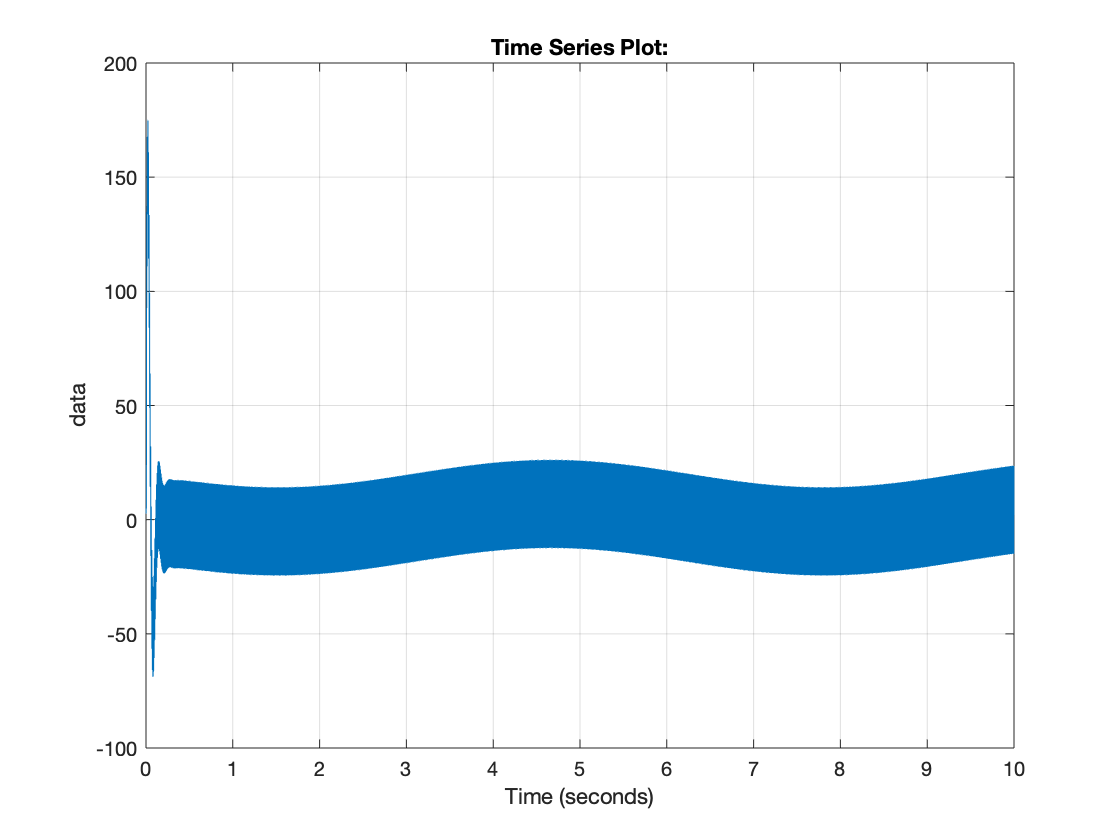

plot(out.u); grid on;